Generated in MATLAB R2023a on by PLX & Luorong  2025-10-26 19:39:12

% 生成时间戳并显示 Image Acquisition 工具箱的 GUI
clear all;
clc; sca; imaqreset  % 清理变量、清空命令行、关闭 PTB 窗口、重置图像采集硬件连接

PTB-INFO: Multi-display setup in explicit multi-display mode detected. Using the following mapping:
PTB-INFO: Screen 0 corresponds to the full Windows desktop area. Useful for stereo presentations in stereomode=4 ...
PTB-INFO: Screen 1 corresponds to the display area of the monitor with the Windows-internal name \\.\DISPLAY1 ...
PTB-INFO: Screen 2 corresponds to the display area of the monitor with the Windows-internal name \\.\DISPLAY2 ...



% ============== 手动修改参数 ====================
root_path = 'E:\test'; % 数据存储根目录
Hikron = false; % 是否启用海康威视 (Hikvision/Hikron) 相机标记
% ================================================

device_list = {};         % 初始化设备列表
mkdir(root_path)          % 创建存储文件夹
mpath = fullfile(root_path,'methindex.mat');
if exist(mpath, 'file')
    load(mpath, 'methindex');
    cfg.methindex = methindex;
else
    methindex = 0;
    cfg.methindex = methindex; % 初始值
    save(mpath,'methindex')
end
recordmodes = {'record','visualstim'};  % {'record','visualstim'}

recordmodes = 1×2 cell array
    {'record'}    {'visualstim'}


recordmode = recordmodes{1}; %  %record % 
% mkdir(fullfile(root_path,sprintf('Methods%d', cfg.methindex)))  

## Connect to Camera

Create connection to the device using the specified adaptor with the specified format.

# DO NOT operate the imaging GUI window before this section

% 连接相机
% 使用指定的适配器（hamamatsu）和格式创建设备连接
% 注意：在运行此段代码前，不要在 GUI 窗口中操作相机，否则可能导致端口占用
info = imaqhwinfo('hamamatsu');      % 获取 hamamatsu 适配器的硬件信息

num.cameras = length(info.DeviceInfo); % 检测到的相机数量
fprintf('%0d camera(s) found.\n', num.cameras)

1 camera(s) found.


device_list = {};

for i = 1:num.cameras
    dev_name = info.DeviceInfo(i).DeviceName; % 获取相机设备名称
    device_list{end+1} = dev_name;            % 存入列表
    fprintf('Device ID %d: %s\n', i, dev_name); % 在命令行打印每个相机的 ID 和名称
end

Device ID 1: C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8



v = cell(num.cameras,1);   % 用于存储视频输入对象 (videoinput)
src = cell(num.cameras,1); % 用于存储相机的源属性 (selectedsource)

for i = 1:num.cameras
    % 创建视频采集对象：
    % 参数 1: 适配器名 "hamamatsu"
    % 参数 2: 设备 ID (i)
    % 参数 3: 采集格式 "MONO16_2304x2304_Fast" (16位灰度，全分辨率 2304x2304)
    v{i} = videoinput("hamamatsu", i, "MONO16_2304x2304_Fast");
    
    % 获取该相机的底层配置句柄（用于设置曝光、触发等物理参数）
    src{i} = getselectedsource(v{i});
end

imageAcquisitionExplorer; % 打开 MATLAB 自带的图形化采集界面（便于手动检查相机状态）

fprintf('Camera(s) linked.\n') % 提示相机连接成功

Camera(s) linked.


## Connect to DAQ

Create connection to the NI controler using the specified adaptor with the specified format.

### Camera 2326 

external trigger: `Dev1/port0/line9`

timing: User2/PFI3 ~ ctr 1                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

### Camera 2325 

external trigger: `Dev1/port0/line10`

timing: PFI0 ~ ctr 2 

%% --- DAQ 硬件通道分配与功能标签化 ---

% 设定触发模式与端口映射表
trigger = true;
camera_ports = {'port0/line9','port0/line10'}; % DO 端口：用于发送触发指令给相机
input_ports = {'ctr1','ctr2'};                 % Counter 端口：用于接收相机回传的帧同步信号
camera_names = { ...                           % 相机全名列表，用于与硬件检测结果匹配
    'C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8';
    'C14440-20UP, S/N: 002325, Bus: USB3'};

% 初始化 NI-DAQ 采集对象
d.out = daq('ni');
d.in = daq('ni');
d.in.Rate = 40000;

d.device = 'Dev1';
dinfo = daqlist("ni");
% disp(dinfo{1,'DeviceInfo'}); % 在命令行显示板卡详细信息（如型号、序列号）

% 初始化功能标签列表
d.channeltypes.out = {}; 
d.channeltypes.in = {}; 

% 如果 DAQ 对象中已有老旧通道，全部清空，确保索引从 1 开始
if ~isempty(d.out.Channels)
    removechannel(d.out)
end
if ~isempty(d.in.Channels)
    removechannel(d.in)
end

% 添加影子通道 (只需一个 ai0 即可激活整个对象的硬件时钟)
addinput(d.in, d.device, "ai0", "Voltage"); 
d.channeltypes.in{end+1} = 'Clock';  % 立即打上输入标签

% 根据检测到的相机数量，循环配置通道
for i = 1:num.cameras
    % 1. 匹配当前连接的相机在 camera_names 列表中的索引
    indexC = strfind(camera_names, info.DeviceInfo(i).DeviceName);
    index = find(~cellfun('isempty', indexC)); 
    
    % 2. 添加数字输出通道 (Digital Output)
    % 功能：发送外部触发脉冲启动相机
    addoutput(d.out, d.device, camera_ports{index}, 'Digital');
    d.channeltypes.out{end+1} = ['camera_DO_' device_list{i}]; % 立即打上输出标签

    % 3. 添加计数器输入通道 (Edge Count Input)
    % 功能：实时累加相机回传的 ExposureEnd/Readout 脉冲，精确记录帧数
    addinput(d.in, d.device, input_ports{index}, 'EdgeCount'); 
    d.channeltypes.in{end+1} = ['camera_timing_' device_list{i}];  % 立即打上输入标签
end

 % 3. 添加软件盖戳通道 (Edge Count Input)
addinput(d.in, d.device, 'ctr0', "Position");
d.channeltypes.in{end+1} = 'Internalstamp';  % 立即打上输入标签
addoutput(d.out, d.device, 'port0/line7', 'Digital'); % to PFI8
d.channeltypes.out{end+1} = 'Internalstamp';  % 立即打上输入标签
try
    clk = addclock(d.out,"ScanClock","External","Dev1/PFI8");%
catch
end

% 初始化硬件状态
resetcounters(d.in);  % 将所有计数器归零
write(d.out, zeros(1,num.cameras+1));       % 确保所有 Digital Output 通道初始状态为低电平 (Off)



% 实验状态标志位
registed = false;  % 相机空间配准标志


## Set light source

# Light intensity must be set in web app

### `Light source`

`Laser405 Dev1/port0/line23`

`Laser445 DO: Dev1/port0/line11 AO:/ao2`

`LEDcyan Dev1/port0/line12`

`LEDgreen Dev1/port0/line16`

`LEDred Dev1/port0/line18`

%% --- 光源物理映射与参数定义 ---
% 定义硬件端口与光源名称的对应关系
channel_group = {'Laser405','Laser445','LEDcyan','LEDgreen','LEDred'};
light_port = {"port0/line23","port0/line11","port0/line12","port0/line16","port0/line18"};
colors = {'m','b','b','g','r'}; % 绘图建议颜色

% ============== 手动修改参数 ====================
% 根据channel_group选择本次实验要使用的光源索引。例如 [3, 5] 代表使用 LEDcyan 和 LEDred
light_channel = [4]; 
% ================================================

% 3. 安全性检查：本实验逻辑目前仅支持单个刺激光源
if length(light_channel)-num.cameras > 1
    error('错误：刺激光源数量大于 1，请检查 light_channel 设置.')
elseif length(light_channel) < num.cameras
    warning('警告：成像光数量小于相机数量，请检查 light_channel 设置.')
end

%% --- 光源逻辑分配 (刺激 vs 成像) ---
% 1. 获取选定的光源名称列表
lightls.used = channel_group(light_channel);

% 2. 自动分配规则：列表中最后 N 个光源设定为成像光 (N = 运行的相机数量)
% 其余的光源设定为刺激光
lightls.img = lightls.used(end-num.cameras+1:end); 
lightls.stim = setdiff(lightls.used, lightls.img, 'stable'); % 保持原始顺序，提取刺激光

num.imlsrc = length(lightls.img); % 成像光源数量
num.stlsrc = length(lightls.stim); % 刺激光源数量


% 打印光源分配报告
fprintf('\n--- 光源配置完成 ---\n');


--- 光源配置完成 ---


fprintf('选定光源总数: %d\n', length(lightls.used));

选定光源总数: 1


fprintf(' -> 刺激光源 (Stim): %d [%s]\n', num.stlsrc, strjoin(lightls.stim, ', '));

 -> 刺激光源 (Stim): 0 []


fprintf(' -> 成像光源 (Img):  %d [%s]\n', num.imlsrc, strjoin(lightls.img, ', '));

 -> 成像光源 (Img):  1 [LEDgreen]


fprintf([repmat('-', 1, 50)  '\n']);

--------------------------------------------------



%% --- DAQ 通道清理与光源硬件配置 ---
% 如果 DAQ 对象中已有的通道数超过了相机占用的部分（相机占用 2*num.cameras）
% 则清除后续旧通道，防止重复添加导致的索引混乱
if length(d.out.Channels) > num.cameras+1
    d.channeltypes.out = d.channeltypes.out(1:(num.cameras)+1);
    removechannel(d.out, (num.cameras+2):length(d.out.Channels));
end

% 遍历选定的 channel 索引，将其添加至 DAQ 输出列表
for i = 1:length(light_channel)
    % A. 添加数字输出通道 (Digital Output)
    addoutput(d.out, d.device, light_port{light_channel(i)}, 'Digital');
    
    % B. 根据逻辑分配结果，打上对应的功能标签
    % 前 i <= num.stlsrc 的光源被标记为刺激光，其余为成像光
    if i <= num.stlsrc
        d.channeltypes.out{end+1} = ['light_stim_DO_' lightls.used{i}]; % 刺激光数字开关
    else
        d.channeltypes.out{end+1} = ['light_img_DO_' lightls.used{i}];  % 成像光数字开关
    end

    % C. 特殊硬件处理：如果使用的是 Laser445 (索引为 2)
    % 除了数字开关，还需添加模拟输出通道 (AO) 来控制功率
    if light_channel(i) == 2
        addoutput(d.out, d.device, 'ao2', 'Voltage');
        d.channeltypes.out{end+1} = ['light_stim_AO_' lightls.used{i}]; % 刺激光模拟电压
    end
end


## Set DMD

### DMD 

`Dev1/port0/line8`

addoutput(d.out,d.device,'port0/line8','Digital');
d.channeltypes.out{end+1} = 'DMD_DO' ;
num.DMD = 1; % num of stimulate light source;

## Align Two Cameras (if two cameras were used)

Snap photos by two cameras

# Please turn on the light source manually!

% preset cameras
ROI{1} = [0 0 2304 2304];
ROI{2} = [0 0 2304 2304];

v{1}.ROIPosition = ROI{1};
src{1}.ExposureTime = 20e-03;

v{2}.ROIPosition = ROI{2};
src{2}.ExposureTime = 20e-03;

Snap photos

im25 = getsnapshot(v{1});
im26 = getsnapshot(v{2});
im25 = im25';

### Register images

fprintf('Registering images...\n')
tic;
registermode ='multimodal' ;
% 创建优化器和度量
[optimizer, metric] = imregconfig(registermode);
% optimizer.GradientMagnitudeTolerance = 1e-2;
% optimizer.MaximumStepLength = 10; % 增大最大步长，应对大偏移
% optimizer.MinimumStepLength = 1e-7; % 减小最小步长，提高最终精度
optimizer.MaximumIterations = 100;  % 增加迭代次数
optimizer.InitialRadius = 0.008;
% optimizer.RelaxationFactor = 0.3;   % 调整松弛因子，影响收敛速度

% % 执行配准
tform = imregtform(im25, im26, 'translation', optimizer, metric);
fprintf(sprintf('Registered after %0d s.\n',toc))
% 提取偏移量
x_offset = tform.T(3,1);
y_offset = tform.T(3,2);

fprintf('计算出的偏移量: x_offset = %.2f, y_offset = %.2f\n', x_offset, y_offset);
fprintf('centered camera2325 = %d, %d\n', round(896 - y_offset), round(896 - x_offset));

registered_im25 = imtranslate(im25, [x_offset,y_offset]);
% 显示配准结果
figure
subplot(1,3,1);
imshowpair(im25,im26);
title('配准前叠加');

% 应用变换
subplot(1,3,2);
imshowpair(registered_im25,im26);
title('配准后叠加');

### Apply offset

registed = true;
ROI{1} = [round(896 - y_offset) round(896 - x_offset) 512 512];
ROI{2} = [896 896 512 512];

v{1}.ROIPosition = ROI{1};
v{2}.ROIPosition = ROI{2};

### Reimaging

im25 = getsnapshot(v{1});
im26 = getsnapshot(v{2});
im25 = im25';

subplot(1,3,3);
imshowpair(im26, im25);
title('更换offset后重新拍摄');


fig_filename = fullfile(root_path, '0_register_image.fig');
png_filename = fullfile(root_path, '0_register_image.png');
mat_filename = fullfile(root_path, '0_register_image.mat');

saveas(gcf, fig_filename, 'fig');
saveas(gcf, png_filename, 'png');
save(mat_filename, 'registermode','optimizer','metric','x_offset','y_offset','tform');

## Configure Default Device Properties for Voltage Recording

Configure videoinput properties to prepare for acquisition.

%% --- 相机默认属性与采集配置 ---
% 设置视频输入对象的触发模式：'immediate' 表示 start(v) 后立即准备，'manual' 表示手动触发
triggermode = 'immediate'; 

% ============== 手动修改参数 ====================
bin = [1,1];                 % Binning 系数 (1, 2, 4) [camera1,camera2]
ROI{1} = [896 896 512 512];  % 相机 1 的采集区域 [X起点 Y起点 宽度 高度]
ROI{2} = [896 896 512 512];  % 相机 2 的采集区域
eptime = 2.4931e-03;            % 曝光时间 (单位: 秒, 399.7 Hz)
% ================================================
binmode = {};


for i = 1:num.cameras
    % 1. 根据 Binning 系数选择对应的相机运行模式字符串
     b = bin(i);
        if b == 1
            binmode{i} = 'MONO16_2304x2304_Fast';
        elseif b == 2
            binmode{i} = "MONO16_BIN2x2_1152x1152_Fast";
        elseif b == 4
            binmode{i} = "MONO16_BIN4x4_576x576_Fast";
        end
    
    % 2. 检查是否需要重新初始化
    need_reinit = true;
    if exist('v', 'var') && length(v) >= i && isvalid(v{i})
        if strcmp(v{i}.VideoFormat, binmode{i})
            need_reinit = false;
        end
    end

    if need_reinit
        v{i} = videoinput("hamamatsu", i, binmode{i});
        src{i} = getselectedsource(v{i});
        fprintf('Camera %d was changed to bin%d.\n', i, b)
    end

    % 3. 独立调整每个相机的 ROI
    % 逻辑：始终基于原始 ROI 数组除以当前的 bin 系数
    if ~registed
        v{i}.ROIPosition = round(ROI{i} ./ b);
    else
        % 如果已经配准，假设 ROI 已经是缩放后的，或者是特定逻辑
        % 通常建议在设置 bin 时重置为标准 ROI 
        v{i}.ROIPosition = round(v{i}.ROIPosition ./ b);
    end

    % 4. 循环设置每个相机的具体采集属性
    v{i}.TriggerRepeat = 0;       % 触发重复次数：0 代表只触发一次开始
    v{i}.FramesPerTrigger = Inf;  % 每次触发采集的帧数：设置为无限，由 stop 命令停止
    
    src{i} = getselectedsource(v{i});
    src{i}.ExposureTime = eptime; % 设置曝光时间
    
    % 配置视频对象触发环境
    triggerconfig(v{i}, triggermode);
    
    % 如果启用了硬件同步触发 (trigger = true)
    if trigger
        src{i}.TriggerSource = 'external'; % 信号来源：外部引脚 (如 CXP 或 USB3 触发线)
        src{i}.TriggerPolarity = "positive"; % 触发极性：正脉冲 (与 DAQ 的 write(d,1) 匹配)
        src{i}.TriggerMode = 'start';      % 触发行为：仅作为开始信号 (Start Trigger)
        % 关键的输出配置 (Timing 输出)
        src{i}.OutputTriggerKindOpt1 = 'programable';
        src{i}.OutputTriggerSourceOpt1 = 'vsync'; % E:\3_Hardware\ORCA_fusion\Help\C14440-20UP_IM_En.pdf P48
        src{i}.OutputTriggerPolarityOpt1 = 'positive';
    end
end

Camera 1 was changed to bin1.





%% --- 5. 打印相机配置汇总 ---
fprintf(['\n'  repmat('=',1,40)  '\n']);


fprintf('相机独立配置汇总:\n');

相机独立配置汇总:


for i = 1:num.cameras
    actualROI = v{i}.ROIPosition;
    fprintf('Cam %d: Bin=%d | Format=%s\n', i, bin(i), v{i}.VideoFormat);
    fprintf('       ROI: [X:%d Y:%d W:%d H:%d] | Exp: %.2fms\n', ...
            actualROI(1), actualROI(2), actualROI(3), actualROI(4), eptime*1000);
end

Cam 1: Bin=1 | Format=MONO16_2304x2304_Fast


       ROI: [X:896 Y:896 W:512 H:512] | Exp: 2.49ms



fprintf(['\n'  repmat('=',1,40)  '\n']);

## Screen stimulation preparation

### generate grafting drift config for test

%% --- 基于 DriftDemo4 逻辑的实时渲染脚本 ---
% --- 1. 配置 ---      
recordmode = recordmodes{2};
   
stimCfg.videoWidth = 800;
stimCfg.videoHeight = 480;
stimCfg.duration = 1.5;
stimCfg.isi = 0.5;  
stimCfg.numorien = 8;
stimCfg.orientations = 0:360/stimCfg.numorien:360*(1-1/stimCfg.numorien); % 定义方向
stimCfg.amp        =  0.5; % 100% 对比度 (从0.5-0.5到0.5+0.5);
stimCfg.SF = 0.04; % Spatial frequency cpd cycle per degree
stimCfg.TF = 2; % temproal frequency Hz
stimCfg.distToScreen = 9;       
stimCfg.screenWidthCm = 11; 

stimCfg.totalVisualAngle = 2 * atand((stimCfg.screenWidthCm / 2) / stimCfg.distToScreen);
stimCfg.pixelsPerDegree = stimCfg.videoWidth / stimCfg.totalVisualAngle;
stimCfg.cps = stimCfg.TF; % cycles per seconds
stimCfg.cpp = stimCfg.SF / stimCfg.pixelsPerDegree; % cycles per pixel
stimCfg.camFPS     = 1/eptime;

% --- 2. PTB 初始化 ---
ListenChar(0);
PsychDefaultSetup(2);
screenNumber = max(Screen('Screens'));
% 强制开启硬件加速检查
AssertOpenGL;
Screen('Preference', 'WindowShieldingLevel', 0);
Screen('Preference', 'SkipSyncTests', 0);
Screen('Preference', 'VisualDebugLevel', 3); % 减少启动时的干扰信息
[stimCfg.window, stimCfg.windowRect] = PsychImaging('OpenWindow', screenNumber, 0.5);

PTB-INFO: Proper timing and timestamping of visual stimulus onset is not reliably supported at all
PTB-INFO: when running in windowed mode (non-fullscreen). If PTB aborts with 'Synchronization failure'
PTB-INFO: you can disable the sync test via call to Screen('Preference', 'SkipSyncTests', 2); .
PTB-INFO: You won't get proper stimulus onset timestamps in any case though, so windowed mode is of limited use.
PTB-INFO: The detected endline of the vertical blank interval is equal or lower than the startline. This indicates
PTB-INFO: that i couldn't detect the duration of the vertical blank interval and won't be able to correct timestamps
PTB-INFO: for it. This will introduce a very small and constant offset (typically << 1 msec). Read 'help BeampositionQueries'
PTB-INFO: for how to correct this, should you really require that last few microseconds of precision.
PTB-INFO: Btw. this can also mean that your systems beamposition queries are slightly broken. It may help timing precision to
PTB


% --- 3. 创建过程纹理 (Procedural Grating) ---
% 这是 DriftDemo4 的核心：创建一个“数学公式”纹理
% 参数 [0.5 0.5 0.5 0.0] 是背景灰度 offset
% 计算屏幕对角线长度，确保旋转时四个角不会发白/发灰
stimCfg.gratingsize = ceil(sqrt(stimCfg.videoWidth^2 + stimCfg.videoHeight^2));
stimCfg.gratingtex = CreateProceduralSineGrating(stimCfg.window, stimCfg.gratingsize, stimCfg.gratingsize, [0.5 0.5 0.5 0.0]);

Compiling all shaders matching BasicSineGratingShader * into a GLSL program.
Building a fragment shader:Reading shader from file E:\0_Code\Psychtoolbox-3-3.0.19.15\Psychtoolbox\PsychOpenGL\PsychGLSLShaders\BasicSineGratingShader.frag.txt ...
Building a vertex shader:Reading shader from file E:\0_Code\Psychtoolbox-3-3.0.19.15\Psychtoolbox\PsychOpenGL\PsychGLSLShaders\BasicSineGratingShader.vert.txt ...


grayValue = 128;
stimCfg.grayArray = uint8(ones(10, 10) * grayValue);
stimCfg.grayTex = Screen('MakeTexture', stimCfg.window, stimCfg.grayArray);
stimCfg.ifi = Screen('GetFlipInterval', stimCfg.window);
stimCfg.phaseinc = (stimCfg.cps * 360) * stimCfg.ifi; % 每帧旋转的角度


### Loop test

% --- 4. 实验循环 ---
tic
try
    AssertGLSL; % 确保显卡支持着色器
    
    % 获取初始基准时间 (Anchor)
    vbl = Screen('Flip', stimCfg.window); 
    
    for angle = stimCfg.orientations
        % ================== A. ISI 阶段 ==================
        % 目标：保持灰色背景直到 isi 时间结束
        numFramesISI = round(stimCfg.isi / stimCfg.ifi);
        
        for f = 1:numFramesISI
            Screen('FillRect', stimCfg.window, 0.5);
            
            % 精确控制：在上一帧 vbl 后的 0.5 个 ifi 之后请求翻页
            % 
            vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);
        end

        % ================== B. 刺激阶段 ==================
        phase = 0;
        numFramesStim = round(stimCfg.duration / stimCfg.ifi);
        
        for f = 1:numFramesStim
            % 更新相位
            phase = phase + stimCfg.phaseinc;
            
            % 使用 DrawTexture 绘制
            Screen('DrawTexture', stimCfg.window, stimCfg.gratingtex, [], [], angle, [], [], [], [], [], [phase, stimCfg.cpp, stimCfg.amp, 0]);
            
            % % --- DAQ 触发建议：在 Flip 之前发送准备信号 ---
            % if f == 1
            %     % 这里的信号将会在接下来的那次物理刷新瞬间被标记
            %     fprintf('方向 %d °开始渲染\n', angle);
            % end

            % 精确控制：严格按照 1 个 ifi 的增量进行请求
            % vbl + 0.5 * stimCfg.ifi 给了系统半帧的容错时间
            vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);
        end
        

    end
        % 每一段结束后的清屏
        Screen('FillRect', stimCfg.window, 0.5);
        vbl = Screen('Flip', stimCfg.window); % 重置基准时间
catch ME
    rethrow(ME);
end



PTB-ERROR: Screen('Flip'); beamposition timestamping computed an *impossible stimulus onset value* of 591202.315865 secs, which would indicate that
PTB-ERROR: stimulus onset happened *before* it was actually requested! (Earliest theoretically possible 591202.319439 secs).

PTB-ERROR: Some more diagnostic values (only for experts): rawTimestamp = 591202.320632, scanline = 137
PTB-ERROR: Some more diagnostic values (only for experts): line_pre_swaprequest = 99, line_post_swaprequest = 132, time_post_swaprequest = 591202.320495
PTB-ERROR: Some more diagnostic values (only for experts): preflip_vblcount = 0, preflip_vbltimestamp = 591202.316011
PTB-ERROR: Some more diagnostic values (only for experts): postflip_vblcount = 0, postflip_vbltimestamp = -1.000000, vbltimestampquery_retrycount = 0

PTB-ERROR: This error can be due to either of the following causes:
PTB-ERROR: Very unlikely: Something is broken in your systems beamposition timestamping. I've disabled high precision
PTB-ERROR: t

toc

Elapsed time is 16.019562 seconds.


### Single orientation test

%% --- 精确时序单次触发播放脚本 ---
tic
% 1. 自动初始化/检查索引
if ~exist('stim_count', 'var')
    stim_count = 1;
end

% 2. 边界检查
if stim_count > length(stimCfg.orientations)
    stim_count = 1;
    fprintf('>>> 已完成一轮刺激，重置回第一个方向。\n');
end

% 获取当前角度
current_angle = stimCfg.orientations(stim_count);

try
    % --- 0. 捕获初始基准时间 ---
    % 这一步非常重要，它决定了后续所有帧的参考坐标系
    vbl = Screen('Flip', stimCfg.window);

    % --- 1. 播放 ISI (灰色) ---
    numFramesISI = round(stimCfg.isi / stimCfg.ifi);
    for f = 1:numFramesISI
        Screen('FillRect', stimCfg.window, 0.5);
        
        % 时间控制：在基准 vbl 后的第 f 帧请求翻页
        % 减去 0.5*ifi 是为了给系统留出半帧的计算缓冲时间
        vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);
    end

    % --- 2. 播放刺激 ---
    phase = 0;
    numFramesStim = round(stimCfg.duration / stimCfg.ifi);
    
    % 绘制区域居中
    dstRect = CenterRectOnPoint([0 0 stimCfg.gratingsize stimCfg.gratingsize], ...
        stimCfg.videoWidth/2, stimCfg.videoHeight/2);

    for f = 1:numFramesStim
        phase = phase + stimCfg.phaseinc;
        
        % 绘制过程纹理
        Screen('DrawTexture', stimCfg.window, stimCfg.gratingtex, [], dstRect, ...
            current_angle, [], [], [], [], [], [phase, stimCfg.cpp, stimCfg.amp, 0]);
        
        % 精确控制每一帧的呈现时刻
        vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);
        
        % 第一帧触发 DAQ (紧跟在 Flip 之后，记录物理翻页后的瞬间)
        if f == 1
            fprintf('正在运行: 方向 %d/%d | 角度: %d°\n', ...
                stim_count, length(stimCfg.orientations), current_angle);
            % 这里插入你的 DAQ 触发脉冲
            % write(d.out, [0 0 1]); 
        end
    end

    % 结束后恢复灰色并保持最后一帧的时序
    Screen('FillRect', stimCfg.window, 0.5);
    vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);

    % --- 3. 索引递增 ---
    stim_count = stim_count + 1;

catch ME
    rethrow(ME);
end
toc

### Link to gentl Camera

port0/line4

ginfo = imaqhwinfo('gentl');
if isempty(info.DeviceInfo)
    fprintf('no gentl camera found\n')
else
    try
        vh = videoinput("gentl", 1, "Mono8");
        addoutput(d.out,d.device,'port0/line4','Digital');
        outputcount = outputcount + 1 ;
        dindex_hcamera = outputcount;
    end
end
Hikron = true;

vh.FramesPerTrigger = Inf;
srch = getselectedsource(vh);
srch.ExposureTime = 10;
triggerconfig(vh, triggermode);
mkdir(fullfile(root_path,'hikron'));

## Output allocation

### Setting recording parameters

% ==============Manual modified parameters====================
cfg.t.record = 5; % second.
cfg.t.stim = 0.5; % second
cfg.t.stimdelay = 0; %s
cfg.t.stimcycle = 3; % times
d.aostep = [2,5,25]; % percentage. length must be same as the stim cycles
cfg.t.headlength = 5; %s
cfg.t.taillength = ceil(cfg.t.record/20)/2 + 1; %s
% ============================================================

d.aostep = 5.*d.aostep./100; % V. length must be same as the stim cycles
output_idx = find(contains({d.out.Channels.MeasurementType}, {'Output'})); % 找到所有输出通道的物理索引 & contains(d.channeltypes.out, {'DO'})
internal_idx = find(contains(d.channeltypes.out, {'Internal'})); % 找到所有输出通道的物理索引
num.outputs = length(output_idx);
shut = zeros(1,num.outputs);
methindex = methindex + 1; % 初始值
save(mpath,'methindex')
if Hikron
    cfg.nhframes = cfg.t.record*100;
else
    vh = [];
    cfg.nhframes = [];
end

switch recordmode
    case recordmodes{1} % record
        cfg.nframes = cfg.t.record/eptime;

        num.outputframes = cfg.t.record*d.out.Rate;

        % 初始化主输出矩阵 [num.outputframes x OutputChannels]
        output = zeros(num.outputframes, num.outputs);
        % camera_DO = contains(d.channeltypes.out, 'camera_DO');

        %% --- 2. 根据标签生成并分配波形 ---
        for col = 1:num.outputs
            % 获取当前物理通道在 d.channeltypes.out 中对应的标签
            tag = d.channeltypes.out{output_idx(col)};

            % A. 相机触发信号 (Clock)
            if contains(tag, 'camera_DO')
                output(:, col) = generateDigitalSignal('clock', 1/cfg.t.record, d.out.Rate, cfg.t.record);

                % B. 刺激光源数字开关 (Pulse)
            elseif contains(tag, 'light_stim_DO')
                output(:, col) = generateDigitalSignal('pulse', cfg.t.stimcycle/cfg.t.record, d.out.Rate, cfg.t.record, ...
                    'pulseWidth', cfg.t.stim, 'phase', cfg.t.stimdelay);

                % C. 刺激光源模拟电压 (AO Step)
            elseif contains(tag, 'light_stim_AO')
                % 生成基础脉冲掩码
                pulse_mask = generateDigitalSignal('pulse', cfg.t.stimcycle/cfg.t.record, d.out.Rate, cfg.t.record, ...
                    'pulseWidth', cfg.t.stim, 'phase', cfg.t.stimdelay);
                % 生成阶梯电压
                steps = repelem(d.aostep, ceil(num.outputframes/length(d.aostep)));
                steps = steps(1:num.outputframes)';
                output(:, col) = pulse_mask .* steps;

                % D. 成像光源 (长开信号)
            elseif contains(tag, 'light_img_DO')
                output(:, col) = generateDigitalSignal('pulse', 1/cfg.t.record, d.out.Rate, cfg.t.record,'pulseWidth',cfg.t.record);

                % E. 海康相机触发 (如果启用)
            elseif  contains(tag, 'hikron') && Hikron
                output(:, col) = generateDigitalSignal('clock', 1/cfg.t.record, d.out.Rate, cfg.t.record);
            
                % E. 内部信号记录
            elseif  contains(tag, 'Internalstamp')
                output(:, col) = zeros(num.outputframes,1);
            end
        end

## Allocate to DO Output

DAQ 序列构造完成:


  - Head 阶段: 5000 samples (5.00 s)


  - Stim 阶段: 5000 samples (5.00 s)


  - Tail 阶段: 1500 samples (1.50 s)


  - 总计时长: 11.50 s


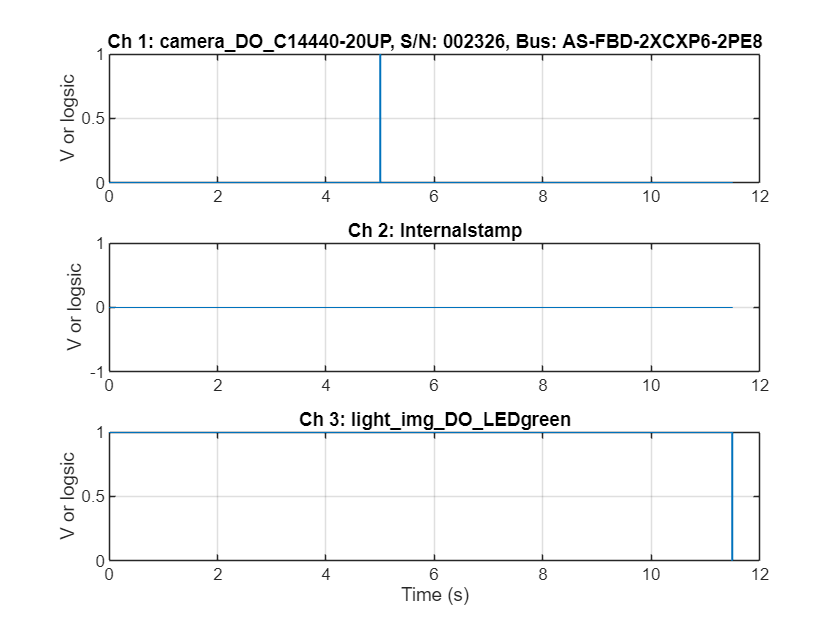


        %% --- 3. 添加 Head (前导) 与 Tail (拖尾) ---
        % Head: 实验开始前 head s，仅打开成像光

        head_samples = round(cfg.t.headlength * d.out.Rate);
        head = zeros(head_samples, num.outputs);
        img_cols = find(contains(d.channeltypes.out(output_idx), 'light_img'));
        head(:, img_cols) = 1;

        % Tail: 实验结束后，成像光多留一段缓冲
        
        tail_samples = round(cfg.t.taillength * d.out.Rate);

        if cfg.nframes ~=inf
            tail = zeros(tail_samples, num.outputs);
            tail(1:end-10, img_cols) = 1;
            output = [head;output; tail];
        else
            tail = ones(tail_samples, num.outputs);
            output = output;
        end


        dt = 0:1/d.out.Rate:(length(output)-1)/d.out.Rate;
        f = figure();

        % --- 打印 Head 和 Tail 设定信息 ---
        fprintf(['\n'  repmat('=',1,30)  '\n']);
        fprintf('DAQ 序列构造完成:\n');
        fprintf('  - Head 阶段: %d samples (%.2f s)\n', head_samples, head_samples/d.out.Rate);
        fprintf('  - Stim 阶段: %d samples (%.2f s)\n', size(output,1)-head_samples-tail_samples, (size(output,1)-head_samples-tail_samples)/d.out.Rate);
        fprintf('  - Tail 阶段: %d samples (%.2f s)\n', tail_samples, tail_samples/d.out.Rate);
        fprintf('  - 总计时长: %.2f s\n', size(output,1)/d.out.Rate);
        fprintf([repmat('=',1,30)  '\n\n']);

        %% --- 4. 自动绘图验证 ---
        f = figure('Name', 'DAQ Output Channels Preview', 'Color', 'w');
        dt = (0:length(output)-1)/d.out.Rate;
        t_tags = d.channeltypes.out(output_idx);

        for i = 1:num.outputs
            subplot(num.outputs, 1, i)
            if cfg.nframes == inf
                plot(dt, output(:, i),'o', 'LineWidth', 1)
            else
                plot(dt, output(:, i), 'LineWidth', 1)
            end
            ylabel('V or logsic')
            title(sprintf('Ch %d: %s', output_idx(i), t_tags{i}), 'Interpreter', 'none')
            grid on
        end
        xlabel('Time (s)')

        % 保存配置
        cfg.output = output;
        mkdir(fullfile(root_path,sprintf('Methods%d', cfg.methindex)))
        saveas(f, fullfile(root_path,sprintf('Methods%d', cfg.methindex), '0_DO_input.png'));
        save(fullfile(root_path,sprintf('Methods%d', cfg.methindex), '0_DO_input.mat'), 'output');

        
    case recordmodes{2} % visualstim
        cfg.nframes = inf;
        % Create normalized signals


        signal.on.all = ones(1,num.outputs);
        signal.off.all = zeros(1,num.outputs);

        signal.on.camera = signal.off.all;
        signal.on.camera(find(contains(d.channeltypes.out, {'camera'}))) = 1;

        signal.on.light.img = signal.off.all;
        signal.on.light.img(find(contains(d.channeltypes.out, {'light_img'}))) = 1;

        signal.on.light.stim = signal.off.all;
        signal.on.light.stim(find(contains(d.channeltypes.out, {'light_stim'}))) = 1;
        % 
        % signal.off.camera = signal.off.all;
        % signal.off.camera = signal.off.all;
        % 
        % signal.off.light.img = ~signal.on.light.img;
        % signal.off.light.stim = ~signal.on.light.stim;


        signal.stamp.onlystamp = signal.off.all;
        signal.stamp.onlystamp(internal_idx) = 1;
        signal.stamp.onlightimg = signal.on.light.img;
        signal.stamp.onlightimg(internal_idx) = 1;

        signal.off.stamp = ~signal.stamp.onlystamp;

        fprintf('进入视觉刺激模式\n');
        save(fullfile(root_path,sprintf('Methods%d', cfg.methindex),'stimcfg.mat'),'stimCfg')
end


cfg.methindex =  cfg.methindex + 1;
cfg.recindex = 0;
methpath = fullfile(root_path,sprintf('Methods%d', cfg.methindex));
mkdir(methpath)
save(fullfile(methpath,'daq.mat'),"d")


## Recording

# Preview in GUI must be OFF before recording

# CHECK light intensity in the Lumencor Light Engine before recording

%% --- 实验参数配置 (Configuration) ---
% ============== Manual modified parameters ====================
cfg.label    = {'test_Cyan5%_10s'};    % for two cameras, use labels like {'Camera1','Camera2'}
cfg.cycles   = 1;                    % 循环次数
cfg.t.rest    = 2;                    % 组间休息 (s)
cfg.savetype = "tif";                % "tif" or "mat"
cfg.recordmode = recordmode;           % 继承外部变量
cfg.hikron    = Hikron;              % 继承外部变量
% ============================================================

if length(cfg.label) ~= num.cameras
    % 报错并停止运行，防止后续保存数据时崩溃
    error('【配置错误】: 检测到 label 包含 %d 个标签，但当前有 %d 个相机。请确保它们数量一致！', ...
        length(cfg.label), num.cameras);
end

% 更新全局记录计数
cfg.recindex = cfg.recindex + 1;
nowtime_str = strrep(string(datetime('now')), ':', '-');

fprintf('>>> 实验开始: 计划执行 %d 个循环。\n', cfg.cycles);

>>> 实验开始: 计划执行 1 个循环。



%% --- 主执行引擎 (Main Execution Engine) ---
total_tic = tic;
% cleanupObj = onCleanup(@() StopHardware(d, v,shut, vh, use_hikron)); % 脚本中断自动急停

try
    for c = 1:cfg.cycles
        fprintf('\n=== Cycle %d / %d Processing ===\n', c, cfg.cycles);
        cycle_tic = tic;

        % 1. [准备] 生成路径与文件夹
        % ------------------------------------------------
        current_paths = CreatePaths(root_path, c, cfg, nowtime_str, num);
        
        % 2. [准备] 硬件布防
        % 停止之前的任务，配置 Buffer，预加载 DAQ
        ArmHardware(d.out, v, vh, cfg);
        fprintf('   [System] Cameras & DAQ Ready.\n');

        % 3. [执行] 启动采集与刺激 (Critical Section)
        % ------------------------------------------------
        % A. 启动相机等待触发
        StartCameras(v, vh, cfg);
        
        % B. 触发同步 (DAQ + 刺激)
        % ... 在主循环内部 ...
        switch cfg.recordmode
            case recordmodes{2}
                fprintf('   [Stim] Running Drifting Grating...\n');
                % 函数执行完后会带回同步日志
                logs =  RunVisualStimulation(d, v, stimCfg, cfg, signal);
                % 4. [结束] 停止硬件
                StopHardware(d, v, shut);
                f = VisualizeSyncLog(logs);
                % --- 后续保存 ---
                save(fullfile(current_paths.rec, 'logs.mat'), 'logs');
                saveas(f, fullfile(current_paths.rec, 'sync.fig'));
                saveas(f, fullfile(current_paths.rec, 'sync.png'));

                fprintf('   [Data] Saving data...\n');
                movie_paths = SaveCameraData(v, current_paths, cfg, lightls, c,logs);
            case recordmodes{1}
                % --> 纯记录模式 (无视频刺激)

                fprintf('   [Rec] Recording (No Stim)...\n');
                % start(d.in,'continuous')% 开始计时
                addinput(d.out, d.device, "ai1", "Voltage"); 
                preload(d.out,cfg.output)
                start(d.out); % 手动触发 DAQ
                % start(d.in,'Continuous');
                % write(d.out,zeros(2,length(d.out.Channels)))
                % write(d.out,cfg.output)
                RunWaitbarTimer(cfg, c);
                % 4. [结束] 停止硬件
                % ------------------------------------------------
                StopHardware(d, v,shut);
                dtype = {d.out.Channels.MeasurementType};
                if strcmp(dtype{end},'Voltage')
                    removechannel(d.out,length(d.out.Channels))
                end

               fprintf('   [Data] Saving data...\n');
               movie_paths = SaveCameraData(v, current_paths, cfg, lightls, c);
        end


        % 5. [保存] 数据读出与存储
        % ------------------------------------------------
        
        if cfg.hikron
            SaveHikronData(vh, root_path, c, nowtime_str); 
        end
        save(fullfile(current_paths.rec,'config.mat'),'cfg')
        fprintf('   [Time] Cycle finished in %.1f s.\n', toc(cycle_tic));

        % 6. [等待] 组间休息
        % ------------------------------------------------
        HandleRest(cfg, toc(cycle_tic), c);

    end

catch ME
    % 错误处理
    fprintf(2, '\n!!! Error occurred: %s\n', ME.message);
    StopHardware(d, v,shut); % 确保硬件停止
    % if cfg.videostim,; end          % 确保 PTB 关闭
    rethrow(ME);
end


=== Cycle 1 / 1 Processing ===


   [System] Cameras & DAQ Ready.


   [Rec] Recording (No Stim)...


   [Data] Saving data...


Creating new stack file: E:\test\Methods3\Rec2_2026-01-13 16-40-21\Cam1_test_Cyan5%_10s\LEDgreen_meth3rec2cyc1_stack01.tif
Finished processing after 6 s, Stacked tif created in E:\test\Methods3\Rec2_2026-01-13 16-40-21\Cam1_test_Cyan5%_10s\LEDgreen_meth3rec2cyc1.tif.
Cam 1 saved in 6.1s.


   [Time] Cycle finished in 25.8 s.



fprintf('\n>>> All cycles completed in %.1f s.\n', toc(total_tic));


>>> All cycles completed in 25.8 s.




%% === 以下为本地功能函数 (放在脚本末尾) ===
function paths = CreatePaths(root_path, c,  cfg, time_str, num)
% 统一管理文件夹结构
    paths.meth = fullfile(root_path, sprintf('Methods%d', cfg.methindex));
    paths.rec   = fullfile(paths.meth,sprintf('Rec%d_%s',cfg.recindex, time_str) );
for i = 1:num.cameras
   
    if cfg.cycles > 1
        paths.cycle{i} = fullfile(paths.rec, sprintf('Cycle%d', c));
        paths.cam{i}   = fullfile(paths.cycle{i}, sprintf('Cam%d_%s',i, cfg.label{i}));
        if ~exist(paths.cycle{i}, 'dir'), mkdir(paths.cycle{i}); end
    else
        paths.cam{i}   = fullfile(paths.rec, sprintf('Cam%d_%s',i, cfg.label{i}));
        paths.cycle{i} = paths.cam{i};
    end
    
    if ~exist(paths.cam{i}, 'dir'), mkdir(paths.cam{i}); end
end
end

function ArmHardware(d, v, vh, cfg)
    % 配置并预热硬件
    stop(d); flush(d);
    
    for i = 1:length(v)
        stop(v{i});
        v{i}.FramesPerTrigger = cfg.nframes + 1; % 加上冗余量防止 Buffer 溢出
    end
    
    if cfg.hikron
        stop(vh);
        vh.FramesPerTrigger = cfg.nhframes;
    end

    % switch cfg.recordmode
    %     case 'record'
    %         preload(d, cfg.output);
    % end
end

function StartCameras(v, vh, cfg)
    for i = 1:length(v), start(v{i}); end
    if cfg.hikron, start(vh); end
end

function StopHardware(d, v,shut, vh, use_hikron)
    if nargin < 4, vh = []; end
    if nargin < 5, use_hikron = 0; end
    for i = 1:length(v), stop(v{i}); end
    if use_hikron, stop(vh); end
    stop(d.out); % 先停触发源
    flush(d.out)
    stop(d.in)
    flush(d.in)

    start(d.in, "Continuous")
    write(d.out,shut)

    stop(d.out)
    flush(d.out)
    stop(d.in)
    flush(d.in)
end

function movie_paths = SaveCameraData(v, paths, cfg, lightls, c, logs)
    movie_paths = cell(1,length(v));
    for i = 1:length(v)
        
        % 获取数据
        try
            data = getdata(v{i}, v{i}.FramesAvailable);

            % 清洗数据维度 (根据实际相机输出调整 squeeze)
            if ~isempty(data)
                switch cfg.recordmode
                    case 'visualstim'
                    cam_name =  logs.sync.Properties.VariableNames{i+3};
                    % 示例：去除不对齐的帧
                    start_frame = logs.sync.(cam_name)(2);
                    end_frame = logs.sync.(cam_name)(end)+ ceil(mean(diff(logs.sync.(cam_name))));
                    data = data(:,:,:,start_frame:end_frame);
                    case 'record'
                    data = data(:,:,:,2:end);
                end
                data = squeeze(data);

            end
            
            % 构建文件名
            base_name = sprintf('%s_meth%drec%dcyc%d', lightls.img{i}, cfg.methindex, cfg.recindex, c);

            % 保存视频
            t_save = tic;
            if strcmp( cfg.savetype, "tif")
                fn = fullfile(paths.cam{i}, [base_name '.tif']);
                movie_paths{i} = fn;
                array2tif(data, fn); % 需确保 array2tif 在路径中
            elseif strcmp(cfg.savetype, "mat")
                fn = fullfile(paths.cam{i}, [base_name '.mat']);
                movie_paths{i} = fn;
                save(fn, "data", "-v7.3", "-nocompression");
            end
            fprintf('Cam %d saved in %.1fs.\n', i, toc(t_save));
                        
        catch inner_ME
            warning('Failed to save Cam %d: %s', i, inner_ME.message);
        end
    end
end

function SaveHikronData(vh, root, cyc_idx, time_str)
    try
        data = getdata(vh, vh.FramesAvailable);
        data = squeeze(data(:,:,:,2:end));
        fn = fullfile(root, 'hikron', sprintf('Recording_cycles_%d_%s.tif', cyc_idx, time_str));
        array2tif(data, fn);
    catch
        warning('Failed to save Hikron data');
    end
end

function RunWaitbarTimer(cfg, cyc_idx)
    % 纯记录模式下的 UI 进度条（含百分比与倒计时）
    total_t = cfg.t.record + cfg.t.headlength + cfg.t.taillength;
    h = waitbar(0, sprintf('Cycle %d Recording: 0%%', cyc_idx), ...
        'Name', 'Recording Status', 'CreateCancelBtn', 'setappdata(gcbf,''canceling'',1)');
    setappdata(h, 'canceling', 0);
    
    steps = 100; % 增加步数使进度显示更平滑
    dt = total_t / steps;
    
    for k = 1:steps
        % 检查用户是否点击取消
        if getappdata(h, 'canceling')
            delete(h); 
            warning('UserCancelled:Recording', '用户手动中止了 Cycle %d 的录制。', cyc_idx); 
        end
        
        % 核心计算
        pause(dt);
        progress = k / steps;
        percentDone = progress * 100;
        remainTime = total_t - (k * dt);
        
        % 更新进度条信息
        % 使用 sprintf 控制百分比显示为整数，并显示剩余秒数
        msg = sprintf('Cycle %d Processing: %.0f%% | Remains %.1f s', ...
                      cyc_idx, percentDone, max(0, remainTime));
        
        waitbar(progress, h, msg);
    end
    
    delete(h);
end

function logs =  RunVisualStimulation(d, v, stimCfg, cfg, signal)

AssertGLSL; % 确保显卡支持着色器
resetcounters(d.in);
start(d.in,'continuous')% 开始计时
write(d.out, signal.off.all);  % 归零
write(d.out, signal.on.light.img); % 打开光源
pause(cfg.t.headlength)
write(d.out, signal.off.stamp);  % 打开相机
% pause(0.01);         % 保持 10ms (软件计时)
write(d.out, signal.on.light.img);  % 拉低电平

logs.vbl = []; 

try
    % 初始化第一个 vbl 戳作为基准
    vbl = Screen('Flip', stimCfg.window); 
    % 记录初始 vbl 戳 ，得到daq和vbl的对应关系
    write(d.out, signal.stamp.onlightimg);
    write(d.out, signal.on.light.img);
    logs.vbl(end+1) = vbl; 
    
    for angle = stimCfg.orientations
        % ================== A. ISI 阶段 ==================
        % 目标：保持灰色背景直到 isi 时间结束
        numFramesISI = round(stimCfg.isi / stimCfg.ifi);
        
        for f = 1:numFramesISI
            Screen('FillRect', stimCfg.window, 0.5);       

            % 精确控制：在上一帧 vbl 后的 0.5 个 ifi 之后请求翻页
            % 这确保了 Flip 动作在下一个 VBL 到达时准时发生
            vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);
            
            % 发送 Flip 后脉冲
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.on.light.img);
            logs.vbl(end+1) = vbl; 
        end

        % ================== B. 刺激阶段 ==================
        phase = 0;
        numFramesStim = round(stimCfg.duration / stimCfg.ifi);
        
        for f = 1:numFramesStim
            phase = phase + stimCfg.phaseinc;
            Screen('DrawTexture', stimCfg.window, stimCfg.gratingtex, [], [], angle, [], [], [], [], [], [phase, stimCfg.cpp, stimCfg.amp, 0]);
                        
            % 精确控制：严格按照 1 个 ifi 的增量进行请求
            vbl = Screen('Flip', stimCfg.window, vbl + 0.5 * stimCfg.ifi);
                        
            % 发送 Flip 后脉冲
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.on.light.img);
            
            logs.vbl(end+1) = vbl;  
        end
        
    end
        % 每一段结束后的清屏并重置 vbl 基准
        Screen('FillRect', stimCfg.window, 0.5);
        vbl = Screen('Flip', stimCfg.window);
catch ME
    rethrow(ME);
end

pause(cfg.t.taillength)

% 停止 DAQ 采集
stop(d.in); 
for i = 1:length(v), stop(v{i}); end

% 1. 读取 DAQ 原始数据 (Timetable 格式)
logs.daq = read(d.in, "all");
flush(d.in)
flush(d.out)

% 提取 DAQ 中的跳变点 (PTB 脉冲)
daq_ptb_raw = double(logs.daq.Dev1_ctr0);
all_onsets = find(diff(daq_ptb_raw) > 0) + 1; 

% 对齐逻辑
n_vbl = length(logs.vbl);
n_daq = length(all_onsets);
n_common = min(n_vbl, n_daq);

if n_vbl == n_daq
    fprintf('Frames aligned.\n')
else
    fprintf(sprintf('Frames dont aligned. VBL:%d, DAQ :%d\n',n_vbl,n_daq));
end
names = logs.daq.Properties.VariableNames;


% 构造整合后的 sync 表
logs.sync = table();

% 调整 ID：第一个点设为 0 (Anchor)，后续依次累加
logs.sync.stimvideo_frame = (0:n_common-1)'; 
logs.sync.PTB_VBL_Time = logs.vbl(1:n_common)'; % 确保是列向量
logs.sync.DAQ_Timestamp = seconds(logs.daq.Time(all_onsets(1:n_common))); 

for i = 1:length(v)
    % 结果列名为 Camera1_Frame, Camera2_Frame
    col_name = sprintf('Camera%s_Frame', mat2str(i));
    logs.sync.(col_name) = double(logs.daq.(names{i+1})(all_onsets(1:n_common)));
end

end

function f = VisualizeSyncLog(logs)
    fmov = 4;
    % 检查数据
    if ~isfield(logs, 'sync') || isempty(logs.sync)
        error('logs 结构体中缺少 sync 表，请先检查数据对齐逻辑。');
    end
    
    time_daq = seconds(logs.daq.Time);
    
    % 创建画布
    f = figure('Color', 'w', 'Position', [100, 100, 1000, 850], 'Name', '视觉刺激同步对齐报告');
    
    % --- 1. 相机采集稳定性分析 ---
    subplot(3, 1, 1);
    hold on;
    % 动态获取列名中包含 'Camera' 的相机列
    cam_cols = logs.sync.Properties.VariableNames(contains(logs.sync.Properties.VariableNames, 'Camera'));
    colors = lines(length(cam_cols));
    
    for i = 1:length(cam_cols)
        % 从原始 DAQ 数据计算实时 FPS
        % 注意：这里使用 raw counter 计算，能反映采集卡看到的每一帧波动
        raw_ctr_name = logs.daq.Properties.VariableNames{i+1}; % 对应 Camera1_Frame 等在 daq 中的源
        cam_counts = double(logs.daq.(raw_ctr_name));
        cam_onsets = find(diff(cam_counts) > 0) + 1;
        
        if ~isempty(cam_onsets)
            inst_fps = 1 ./ diff(time_daq(cam_onsets));
            inst_fps = movmean(inst_fps,fmov);
            plot(time_daq(cam_onsets(1:end-1)), inst_fps, 'Color', [colors(i,:), 0.5], 'LineWidth', 1, ...
                'DisplayName', sprintf('Cam%s Avg: %.1f Hz', mat2str(i), mean(inst_fps)));
            % 绘制平均值线

        end
    end
    title(sprintf('相机录制帧率 (mean %s frames)',mat2str(fmov)));
    ylabel('FPS (Hz)');
    ylim([mean(inst_fps)-10,mean(inst_fps)+10])
    grid on; legend();
    yline(400, 'r--', 'LineWidth', 1.5,'DisplayName', 'FPS 400');
    
    % --- 2. PTB 翻页时间间隔 (IFI) ---
    subplot(3, 1, 2);
    % 计算每一帧 VBL PTB 之间的时间差
    ifi_PTB_ms = diff(logs.sync.PTB_VBL_Time) * 1000; 
    plot(logs.sync.stimvideo_frame(2:end-1), ifi_PTB_ms(2:end), 'b.-', 'MarkerSize', 8, ...
        'DisplayName','PTB');
    hold on;

    % 绘制参考线（假设 60Hz，约 16.67ms）
    ref_ifi = mean(ifi_PTB_ms);
    yline(ref_ifi, 'r--', 'DisplayName',sprintf('Avg PTB IFI: %.2f ms', ref_ifi));

    % 计算每一帧 VBL DAQ 之间的时间差
    ifi_daq_ms = diff(logs.sync.DAQ_Timestamp) * 1000; 
    plot(logs.sync.stimvideo_frame(2:end-1), ifi_daq_ms(2:end), '.-', ...
        'Color',[0.8500    0.3250    0.0980], 'MarkerSize', 4, ...
        'DisplayName','stamped DAQ');
    hold on;

    % 绘制参考线（假设 60Hz，约 16.67ms）
    ref_ifi = mean(ifi_daq_ms);
    yline(ref_ifi, 'k--', 'DisplayName',sprintf('Avg DAQ IFI: %.2f ms', ref_ifi));
    
    title('\bf B. 翻页时间间隔 (IFI)');
    ylabel('Interval (ms)');
    xlabel('Stimulus Frame Index');
    legend()
    grid on;
    
    % --- 3. 硬件对齐延迟分析 ---
    subplot(3, 1, 3);
    % 延迟 = DAQ 记录时间 - PTB 物理 VBL 时间
    vbl_daq_time = logs.sync.DAQ_Timestamp - logs.sync.DAQ_Timestamp(1);
    vbl_ptb_time = logs.sync.PTB_VBL_Time - logs.sync.PTB_VBL_Time(1);
    delay_ms = (vbl_daq_time - vbl_ptb_time) * 1000;
    
    scatter(logs.sync.stimvideo_frame, delay_ms, 24, delay_ms, 'filled');
    colormap(jet);
    cb = colorbar;
    ylabel(cb, 'DAQ-VBL Latency (ms)');
    
    ylabel(' DAQ-VBL Latency');
    xlabel('Stimulus Frame Index');
    title('\bf C. 系统同步延迟 (从 VBL 发生到 DAQ 记录信号)');
    grid on;
    
    % 总体修饰
    sgtitle(sprintf('DAQ-PTB 同步对齐报告 (总帧数: %d)', height(logs.sync)-1), 'FontSize', 14);
    
end


function HandleRest(cfg, elapsed, c)
    % t.rest: 设定的休息总时长
    % elapsed: 这一轮实验已经跑掉的时间
    % c: 当前循环次数
    
    wait_time = cfg.t.rest - elapsed;
    
    if c < cfg.cycles && wait_time > 0
        % 创建一个休息专用的进度条
        hRest = waitbar(0, sprintf('Cycle %d 完成。准备下一轮...', c), ...
            'Name', 'Rest Period', 'CreateCancelBtn', 'setappdata(gcbf,''canceling'',1)');
        setappdata(hRest, 'canceling', 0);
        
        % 进度条刷新频率 (Hz)
        refreshRate = 10; 
        steps = floor(wait_time * refreshRate);
        
        for k = 1:steps
            % 检查是否点击了取消
            if getappdata(hRest, 'canceling')
                delete(hRest);
                warning('UserCancelled:Rest', '用户在休息期间取消了实验。');
            end
            
            % 计算倒计时
            remaining = wait_time - (k / refreshRate);
            prog = k / steps;
            
            % 更新进度条信息
            waitbar(prog, hRest, sprintf('Resting... Remains: %.1f s', max(0, remaining)));
            
            pause(1/refreshRate);
        end
        
        delete(hRest); % 休息结束，关闭进度条
    elseif c < cfg.cycles && wait_time <= 0
        fprintf('   [Rest] 警告：处理时间超过了设定休息时间，将立即开始下一轮。\n');
    end
end

% function SafeStopHardware(d, v, use_hikron)
% % 无论发生什么，都要调用的急停函数
% try 
%     stop(d); flush(d);preload(d,shut);start(d);pause(1);stop(d);flush(d); catch
% end
% for i = 1:length(v), try stop(v{i}); catch, end; end
% if use_hikron, try stop(vh); catch, end; end
% end

# Run this part when LED or laser cannot be shutdown

    stop(d.out); % 先停触发源
    flush(d.out)
    stop(d.in)
    flush(d.in)

    start(d.in, "Continuous")
    write(d.out,shut)

    stop(d.out)
    flush(d.out)
    stop(d.in)
    flush(d.in)

## Online temporary analysis

movie = movies{1}; % for Camera 1
temp_analysis_save_path = fullfile(save_path{1}, 'temp_analysis');
mkdir(temp_analysis_save_path);

### Create map

    %% Create a map (optional)
    t1 = tic; % Start a timer
    fprintf('Creating a map...\n')
    % if the map cannot figure out active cells, please large the bin.
    bin = 1; % defined bin = 4

    [quick_map] = create_map(movie,size(movie,1),size(movie,2),bin);
    map = quick_map;

    % Visualize correlation coefficients as heatmap
    figure()
    imagesc(quick_map);
    colormap turbo;
    title('Sensitivity Map');
    axis image;
    colorbar;
    fig_filename = fullfile(temp_analysis_save_path, '0_Sensitivity_Map.fig');
    png_filename = fullfile(temp_analysis_save_path, '0_Sensitivity_Map.png');
    mat_filename = fullfile(temp_analysis_save_path, '0_Sensitivity_Map.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(mat_filename, 'map');


    t2 = toc(t1); % Get the elapsed time
    fprintf('Finished mask creating after %d s\n',round(t2))

### Cellpose for mask generatopm

    fprintf('cellpose running......\n');
    cp = cellpose(ExecutionEnvironment="gpu");

    movie_vol_2D = squeeze(mean(movie,3));
    avg_image  = (movie_vol_2D - min(movie_vol_2D(:))) / (max(movie_vol_2D(:)) - min(movie_vol_2D(:)));


    avgdia = 15;
    % gamma_image = imadjust(map,[],[],1.2); % recommend raise the gamma factor from 1 to 4.
    gamma_image = imadjust(avg_image,[],[],1.2); % recommend raise the gamma factor from 1 to 4.
    mask = segmentCells2D(cp, gamma_image , ImageCellDiameter = avgdia,CellThreshold = -1, FlowErrorThreshold = 0.4);% CellThreshold = -2, ,  FlowErrorThreshold = 2
    fprintf('%d cells are found.\n',max(mask(:)));
    figure()
    % 使用labeloverlay函数显示图像
    overlayImage = labeloverlay(gamma_image, mask,'Transparency', 0.6);
    % 显示结果
    imshow(overlayImage);
    title('cellpose mask');
    fig_filename = fullfile(temp_analysis_save_path, '0_cellpose_mask.fig');
    png_filename = fullfile(temp_analysis_save_path, '0_cellpose_mask.png');
    mat_filename = fullfile(temp_analysis_save_path, '0_cellpose_mask.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(mat_filename, 'mask');

### ROI selection

    %% Select ROI
    t1 = tic; % Start a timer
    figure()

    % [rois, traces] = select_ROI(movie);
    [rois, traces] = select_ROI(movie, 'mask', []);
    nrois = max(rois.bwmask,[],'all');

    try
        bwmask = rois.bwmask;
    catch ME

    end
    traces_original = traces;

    % if do not need a map, run the following code:
    % map = [];
    % [bwmask, traces] = select_ROI(movie, nrows, ncols, t, mask, map);

    fig_filename = fullfile(temp_analysis_save_path, '1_raw_trace.fig');
    png_filename = fullfile(temp_analysis_save_path, '1_raw_trace.png');
    roi_filename = fullfile(temp_analysis_save_path, '1_raw_ROI.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(roi_filename, 'rois','avg_image','traces');

    % h = msgbox('All rois saved.', 'Done', 'help');
    % uiwait(h);


    tif_filename = fullfile(temp_analysis_save_path, '1_Averaged.tif');

    tiffile = Tiff(tif_filename, 'w');

    tiffile.setTag('ImageLength', size(movie,2));
    tiffile.setTag('ImageWidth', size(movie,1));
    tiffile.setTag('Photometric', Tiff.Photometric.MinIsBlack);
    tiffile.setTag('BitsPerSample', 16);
    tiffile.setTag('SamplesPerPixel', 1);
    tiffile.setTag('RowsPerStrip', 16);
    tiffile.setTag('PlanarConfiguration', Tiff.PlanarConfiguration.Chunky);
    tiffile.setTag('Compression', Tiff.Compression.None);

    tiffile.setTag('Software', 'MATLAB');
    tiffile.write(uint16(movie_vol_2D));
    tiffile.writeDirectory();
    tiffile.close();
    delete(tiffile)


## CHECK

% save_file = fullfile('Recording.tif');
%
% array2tif(movie1,save_file);
figure
plot(0:eptime:eptime*(size(movies{1},3)-1),normalize(squeeze(mean(mean(movies{1},1),2)),'range'))
hold on;
if num.cameras==2
    plot(0:eptime:eptime*(size(movie2,3)-1),normalize(squeeze(mean(mean(movie2,1),2)),'range'))
end
stimV  = VideoReader(video_path);
stmovie = read(stimV,[1 Inf]);
stmovie = squeeze(stmovie(1,1,:,:));
curvestim = plot(0:1/FrameRate:(size(stmovie,2)-1)/FrameRate,normalize(stmovie(1,:),'range'));
% disp(delay);
% realstim = plot((0:1/FrameRate:(size(stmovie,2)-1)/FrameRate)+delay,normalize(stmovie(1,:),'range'));
% legend("Camera2325",'Camera2326','Yellowlight')
legend('Camera2326','Bluelight')
% title("simutaneously recording by 2 cameras via cube set 1")

figure
plot(trails)